# Projekt

Diana Mazurczak 414513

#### załadowanie danych

fname = "Dataset.csv";
d1 = detectImportOptions(fname);
table = readtable(fname);

#### zmiana typu danych, zamiana na strukture timetable

%zamiana foramtu na datę
table.date = datetime(table.date, 'InputFormat', 'uuuu-MM-dd');
%zmiana sposobu wyświetlania daty
table.date.Format = "dd-MMM-uuuu";
t = table2timetable(table);
%nadanie nowych nazw kolumn
t.Properties.VariableNames = ["rok", "miesiac", "dzien", "stan", "Fujita_scale", "osoby_ranne", "ofiary_smiertelne", "pocz_szerokosc_geo", "pocz_dlugosc_geo", "koncowa_szerokosc_geo", "koncowa_dlugosc_geo", "dlugosc_w_milach", "wiatr_w_jardach"]

t = 67558×13 timetable
       date        rok     miesiac    dzien     stan     Fujita_scale    osoby_ranne    ofiary_smiertelne    pocz_szerokosc_geo    pocz_dlugosc_geo    koncowa_szerokosc_geo    koncowa_dlugosc_geo    dlugosc_w_milach    wiatr_w_jardach
    ___________    ____    _______    _____    ______    ____________    ___________    _________________    __________________    ________________    _____________________    ___________________    ________________    _______________

    03-Jan-1950

%zmiana typu danych w kolumnach rok, miesiac i stan
t.rok = string(t.rok);
t.miesiac = string(t.miesiac);
t.stan = categorical(t.stan);

#### dodawanie wartosci brakujacych i ich zliczenie(ismissing)

%zliczenie ile jest wartości brakujących
sum(ismissing(t))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0


%wartość -9 oznacza wartość brakującą
%(informacja zawarta na stronie przy pobieraniu)
t.Fujita_scale = standardizeMissing(t.Fujita_scale, -9);
%nie znalazłam stanu o skrócie VI
t.stan = standardizeMissing(t.stan, 'VI');
%zamiana wartości 0 na wartości NaN, aby program 
%czytał je jako wartośći brakujące
t = standardizeMissing(t, 0, 'DataVariables',{'koncowa_szerokosc_geo','koncowa_dlugosc_geo'} )

t = 67558×13 timetable
       date         rok      miesiac    dzien    stan    Fujita_scale    osoby_ranne    ofiary_smiertelne    pocz_szerokosc_geo    pocz_dlugosc_geo    koncowa_szerokosc_geo    koncowa_dlugosc_geo    dlugosc_w_milach    wiatr_w_jardach
    ___________    ______    _______    _____    ____    ____________    ___________    _________________    __________________    ________________    _____________________    ___________________    ________________    _______________

    03-Jan-1950

%ponowne zliczenie wartośći brakujacych
sum(ismissing(t))

ans =            0           0           0           1         605           0           0           0           0       26363       26363           0           0


#### zliczanie wartości odstających

sum(isoutlier(t.Fujita_scale))

ans = 0

sum(isoutlier(t.dlugosc_w_milach))

ans = 15197

sum(isoutlier(t.wiatr_w_jardach))

ans = 7157

#### dodawanie nowych kolumn i usuwanie zbednych(removevars)

t.dlugosc_w_kilometrach = t.dlugosc_w_milach .* 1.6093;
t.wiatr_w_metrach = t.wiatr_w_jardach .* 0.9144;
t = removevars(t, ["dzien", "rok", "miesiac"]);

#### zamiana kolejnosci kolumn(movevars)

t = movevars(t, "dlugosc_w_kilometrach", "Before","dlugosc_w_milach");
t = movevars(t, "wiatr_w_metrach", "Before","wiatr_w_jardach");
t = movevars(t, "stan", "After","ofiary_smiertelne");

#### laczenie kategorii(mergecats)

kategorie = categories(t.stan);
NewEngland = {'CT', 'ME', 'MA', 'NH', 'RI', 'VT'};
MidAtlantic = {'DE', 'MD', 'NJ', 'NY', 'PA', 'WA'};
TheSouth = {'AL', 'AR','FL', 'GA', 'KY', 'LA', 'MS', 'NC', 'SC', 'TN', 'VA', 'WV'};
TheMidwest = {'IL', 'IN', 'IA', 'KS', 'MI', 'MN', 'MO', 'NE', 'ND', 'SD', 'OH', 'WI'};
TheSouthwest = {'AZ', 'NM', 'OK', 'TX'};
TheWest = {'AK', 'CO', 'CA', 'HI', 'ID', 'MT', 'NV', 'OR', 'UT', 'WA', 'WY'};
t.stan = mergecats(t.stan, NewEngland, 'New England');
t.stan = mergecats(t.stan, MidAtlantic, 'Mid Atlantic');
t.stan = mergecats(t.stan, TheSouth, 'The South');
t.stan = mergecats(t.stan, TheMidwest, 'The Midwest');
t.stan = mergecats(t.stan, TheSouthwest, 'The Southwest');
t.stan = mergecats(t.stan, TheWest, 'The West')

t = 67558×12 timetable
       date        Fujita_scale    osoby_ranne    ofiary_smiertelne        stan         pocz_szerokosc_geo    pocz_dlugosc_geo    koncowa_szerokosc_geo    koncowa_dlugosc_geo    dlugosc_w_kilometrach    dlugosc_w_milach    wiatr_w_metrach    wiatr_w_jardach
    ___________    ____________    ___________    _________________    _____________    __________________    ________________    _____________________    ___________________    _____________________    ________________    _______________    _______________

    03-Jan

#### uzupelnienie wartosci odstajacych(filloutliers)

#### oraz usuniecie wartosci odstajacych(rmoutliers)

sum(isoutlier(t(:, vartype("numeric"))));
t = filloutliers(t, "center", 'DataVariables',{'wiatr_w_metrach', 'wiatr_w_jardach'});
%center - zastępuje wartości odstające średnią wartością danej kolumny
t = filloutliers(t, "clip", 'DataVariables',{'dlugosc_w_kilometrach', 'dlugosc_w_milach'});
%clip - wartości odstające są przycięte do granic wartości ekstremalnych w danym zakresie
tablica_bez_odst = rmoutliers(t(:, "wiatr_w_metrach")); %usuniecie wartosci odstajacych
sum(isoutlier(t(:, vartype("numeric"))));

#### uzupelnienie wartosci brakujacych(fillmissing)

table0 = table;
table.mag = standardizeMissing(table.mag, -9);
table.st = standardizeMissing(table.st, 'VI');
table = standardizeMissing(table, 0, 'DataVariables',{'elat','elon'} )

table = 67558×14 table
     yr     mo    dy       date          st      mag    inj    fat    slat      slon     elat      elon     len     wid 
    ____    __    __    ___________    ______    ___    ___    ___    _____    ______    _____    ______    ____    ____

    1950    1      3    03-Jan-1950    {'IL'}     3      3      0      39.1     -89.3    39.12    -89.23     3.6     130
    1950    1      3    03-Jan-1950    {'MO'}     3      3      0     38.77    -90.22    38.83    -90.03     9.5     150
    1950    1   

sum(ismissing(table))

ans =            0           0           0           0           1         605           0           0           0           0       26363       26363           0           0


table = fillmissing(table,"linear", "DataVariables",{'elat','elon'});
table = fillmissing(table, "nearest","DataVariables","mag")

table = 67558×14 table
     yr     mo    dy       date          st      mag    inj    fat    slat      slon     elat      elon      len     wid 
    ____    __    __    ___________    ______    ___    ___    ___    _____    ______    _____    _______    ____    ____

    1950    1      3    03-Jan-1950    {'IL'}     3      3      0      39.1     -89.3    39.12     -89.23     3.6     130
    1950    1      3    03-Jan-1950    {'MO'}     3      3      0     38.77    -90.22    38.83     -90.03     9.5     150
    1950    

sum(ismissing(table))

ans =      0     0     0     0     1     0     0     0     0     0     0     0     0     0


#### wykres 1

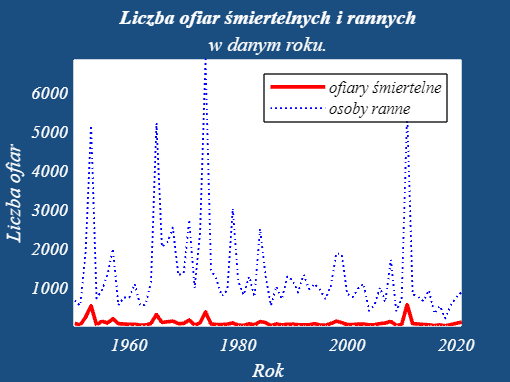

% utworzenie dwoch struktur timetable, ktore
% zwracaja wartosci zsumowane z kazdego roku
ofiary_rocznie = retime(t(:,'ofiary_smiertelne'), "yearly", "sum");
ranni_rocznie = retime(t(:,'osoby_ranne'), "yearly", "sum");
% okreslenie wartosci dla osi x
x = linspace(1950, 2021, 72);
%utworzenie wykresu
p1 = plot(x, ofiary_rocznie.ofiary_smiertelne, x, ranni_rocznie.osoby_ranne);
axis tight;
p1(1).Color = 'red';
p1(2).Color = 'blue';
p1(1).LineWidth = 2;
p1(2).LineStyle = ":";
p1(2).LineWidth = 1;
title('Liczba ofiar śmiertelnych i rannych','w danym roku.', 'Color', 'w', 'FontSize', 11 )
xlabel('Rok')
ylabel('Liczba ofiar')
ax = gca;
ax.FontSize = 10;
ax.FontName = 'Consolac';
ax.FontAngle = "italic";
ax.XColor = 'white';
ax.YColor = 'White';
fig = gcf;
fig.Color = [0.1, 0.3, 0.5];
lgd = legend('ofiary śmiertelne', 'osoby ranne');
lgd.Location = "northeast";

#### wykres 2

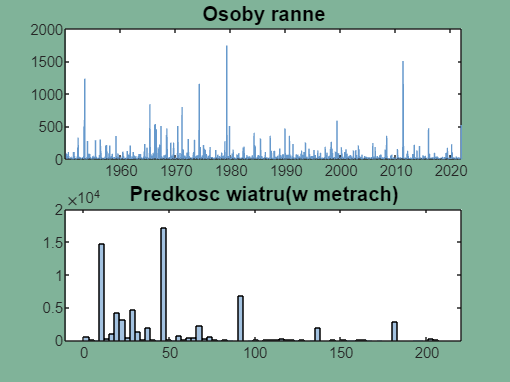

s1a = subplot(2, 2, [1, 2]);
p2a = plot(t.date, t.osoby_ranne, "Color", [0.4,0.6,0.8], 'LineWidth',0.5);
title('Osoby ranne', 'FontName','Arial', 'FontSize', 11);
s1b = subplot(2,2,[3,4]);
h1 = histogram(t.wiatr_w_metrach, 'FaceColor',[0.4,0.6,0.8]);
title('Predkosc wiatru(w metrach)', 'FontName','Arial', 'FontSize', 11);
fig2 = gcf;
fig2.Color = [0.5,0.7,0.6];

#### wykres 3

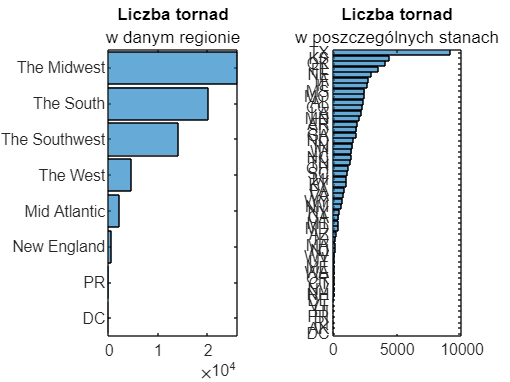

fig3 = figure;
s2a = subplot(1,2,1);
h2a = histogram(t.stan,"Orientation","horizontal", DisplayOrder="ascend");
title('Liczba tornad','w danym regionie')
s2b = subplot(1,2,2);
h2b = histogram(categorical(table.st),"Orientation","horizontal", DisplayOrder="ascend");
title('Liczba tornad','w poszczególnych stanach')

#### wykres 4

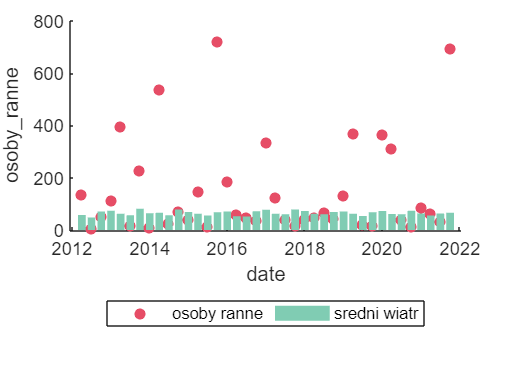

fig4 = figure;
osoby_ranne_rok = retime(t(:,"osoby_ranne"), 'quarterly', 'sum');
osoby_ranne_rok = rmmissing(osoby_ranne_rok);
osoby_ranne_po_2012 = osoby_ranne_rok(250:288, :);
scatter(osoby_ranne_po_2012, "date", "osoby_ranne", "filled", "MarkerEdgeColor","none", "MarkerFaceColor",[0.9, 0.3, 0.4]);
hold on
sredni_wiatr = retime(t(:, "wiatr_w_metrach"), "quarterly", "mean");
wiatr_po_2012 = sredni_wiatr(250:288, :);
b1 = bar(wiatr_po_2012.date, wiatr_po_2012.wiatr_w_metrach, "grouped", "FaceColor",[0.5, 0.8, 0.7], "EdgeColor","none");
legend('osoby ranne', 'sredni wiatr', 'Location','southoutside', 'Orientation','horizontal')
hold off

#### wykres 5

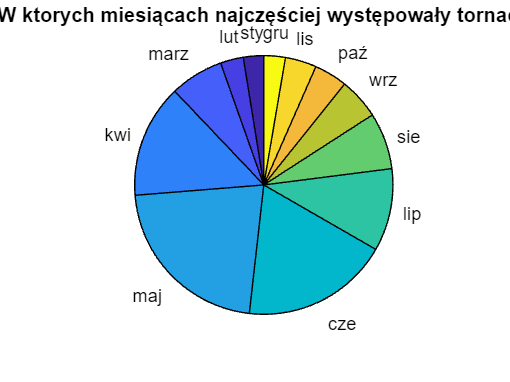

figPie = figure;
labels = ["sty", "lut", "marz", "kwi", "maj", "cze", "lip", "sie", "wrz", "paź", "lis", "gru"];
miesiace = unique(table.mo);
licznik = histcounts(table.mo, max(miesiace));
pie(licznik, labels);
title('W ktorych miesiącach najczęściej występowały tornada');

#### wykres 6

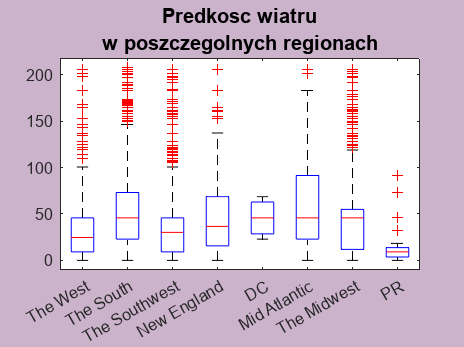

fig5 = figure;
fig5.Color = [0.8, 0.7, 0.8];
boxplot(t.wiatr_w_metrach, t.stan);
title('Predkosc wiatru', 'w poszczegolnych regionach', 'FontSize', 12, 'FontWeight', 'bold');

#### normalizacja danych

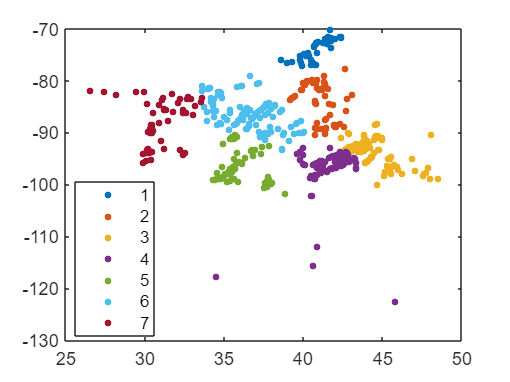

M1 = [table(67000:end, "elat"), table(67000:end, "elon")];
M1 = table2array(M1);
NM1 = normalize(M1, 'norm');
eva1 = evalclusters(NM1,'linkage','CalinskiHarabasz','KList',2:7);
c1 = eva1.OptimalY;
h3 = figure;
gscatter(M1(:,1), M1(:,2), c1)

#### zapisanie przetworzonych danych

save("przetworzone_dane", "t");

#### podzial na probe testowa i uczaca

tbl = table(67000:end, ["len", "slat", "slon","mo", "inj", "wid"])

tbl = 559×6 table
    len      slat      slon      mo    inj    wid
    ____    ______    _______    __    ___    ___

     0.2    41.953    -88.604    8      0      20
     3.9    41.951    -88.596    8      0     400
     1.8    42.063    -88.874    8      0      80
     0.4    42.362    -88.279    8      0      70
     3.8    42.047    -88.591    8      0     100
     1.5    41.962    -88.671    8      0     150
       3     41.47      -89.3    8      0     525
    2.24     47.89     -96.73    8      0     150
    3.65     47.86     -96.85    8      0     200
    0.26     47.56     -98.28    8      0      50
    4.97     48.45     -98.99    8      0     200
    1.09     47.76     -97.67    8      0     150
    2.88     47.67     -97.87    8      0     300
    3.24    42.558    -88.9

%utworzenie macierzy do podzialu
X = table2array(tbl(:, 1:5));
%utworzenie macierzy zawierajacej etykiety klas
Y = tbl.wid;
n = height(X);
%podzial danych na zbior treningowy i testowy
hpartition = cvpartition(n,'Holdout',0.3);
idxTrain = training(hpartition);
%zbior treningowy
XTrain = X(idxTrain,:);
idxTest = test(hpartition);
%zbior testowy
XTest = X(idxTest,:);
YTrain = Y(idxTrain,:);
%analiza czynnikow glownych
[coeff, scoreTrain, ~, ~, explained, mu] = pca(XTrain);
explained

explained =    85.4518
    6.8548
    5.4267
    2.0055
    0.2612


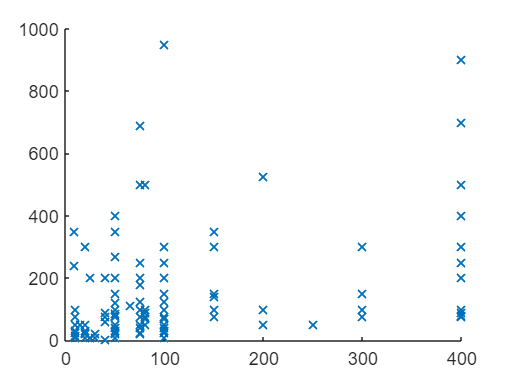

%liczba skladowych, które wyjaśniają co najmniej 95% zmiennosci
idx = find(cumsum(explained)>95, 1);
scoreTrain95 = scoreTrain(:, 1:idx);
%wytrenowanie modelu za pomocą wyznaczonej liczby obserwacji z próby treningowej (fitctree)
mdl = fitctree(scoreTrain95, YTrain);
scoreTest95 = (XTest-mu)*coeff(:,1:idx);
%przewidywanie ocen dla zestawu testowego
YTest_predicted = predict(mdl,scoreTest95);
YTest = Y(idxTest,:);
fig6 = figure;
%porownanie wartości z próby testowej z wartościami przewidzianymi
s6 = scatter(YTest_predicted, YTest, "Marker","x", "LineWidth", 1);

#### Grupowanie 1

Grupowanie za pomoca metody k-means

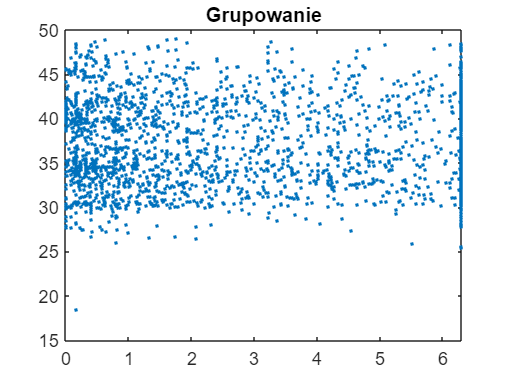

%utworzenie macierzy do pogrupowania
XGrupy = [t.dlugosc_w_kilometrach(65000:end,:), t.pocz_szerokosc_geo(65000:end,:)];
f7 = figure;
%przedstawienie niepogrupowanych danych na wykresie
plot(XGrupy(:,1), XGrupy(:,2), '.');
title('Grupowanie')

%grupowanie za pomoca kmeans
[idx,C] = kmeans(XGrupy,5);
%definicja siatki punktów do wizualizacji
x1 = min(XGrupy(:,1)):0.01:max(XGrupy(:,1));
x2 = min(XGrupy(:,2)):0.01:max(XGrupy(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)];
%przypisanie punktów siatki do odpowiednich klastrów
idx2Region = kmeans(XGrid,5,'MaxIter',1,'Start',C);

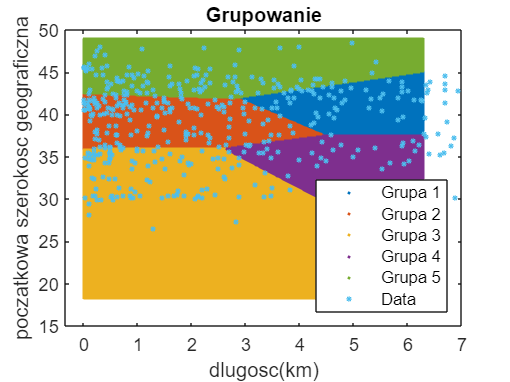

figure;
%przedstaweinie wyników grupowania na wykresie punktowym
gscatter(XGrid(:,1),XGrid(:,2),idx2Region);
hold on;
plot(X(:,1),X(:,2),'*','MarkerSize',3);
title 'Grupowanie';
xlabel 'dlugosc(km)';
ylabel 'poczatkowa szerokosc geograficzna'; 
legend('Grupa 1','Grupa 2','Grupa 3','Grupa 4','Grupa 5','Data','Location','SouthEast');
hold off;

#### Grupowanie 2

Grupowanie za pomocą hierarchicznego klastrowania:

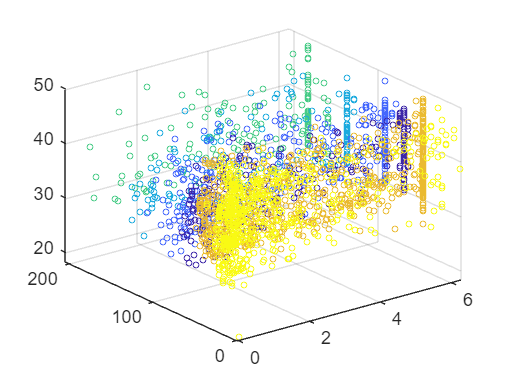

%utworzenie macierzy do pogrupowania
XGrupy2 = [t.dlugosc_w_kilometrach(65000:end,:), t.wiatr_w_metrach(65000:end,:), t.pocz_szerokosc_geo(65000:end,:)];
ZGrupy2 = linkage(XGrupy2, "ward");
CGrupy2 = cluster(ZGrupy2, "maxclust", 6);
figure;
%przedstawienie wyników grupowania na wykresie trójwymiarowym.
SGrupy2 = scatter3(XGrupy2(:,1), XGrupy2(:,2), XGrupy2(:,3), 10, CGrupy2);

#### Klasyfikacja 1

metoda k-means

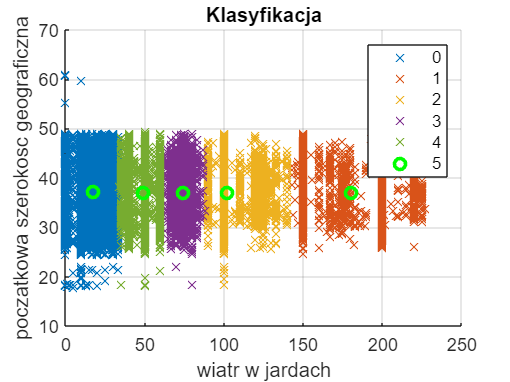

[cindx, ccenter] = kmeans([t.wiatr_w_jardach, t.pocz_szerokosc_geo], 5, 'dist', 'sqeuclidean');
figure;
symbole = t.Fujita_scale;
for i = 1 : 5
    cluster = find(cindx == i);
    scatter(t.wiatr_w_jardach(cluster), t.pocz_szerokosc_geo(cluster), 'Marker','x');
    hold on
end
plot(ccenter(:,1), ccenter(:,2), 'go', 'LineWidth', 2);
title('Klasyfikacja')
legend(categories(categorical(t.Fujita_scale)))
xlabel('wiatr w jardach');
ylabel('poczatkowa szerokosc geograficzna');
grid on

#### Klasyfikacja 2

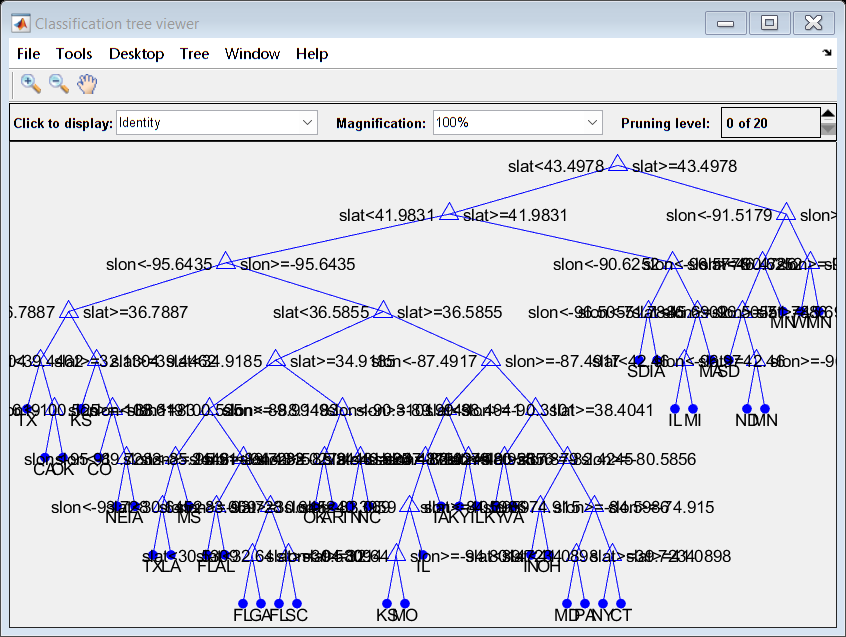

Ytree = table(67000:end, "st");
Xtree = table(67000:end, ["slat", "slon"]);
tree = fitctree(Xtree, Ytree);
% wyswietlenie grafu drzewa decyzyjnego 
view(tree, "Mode","graph")

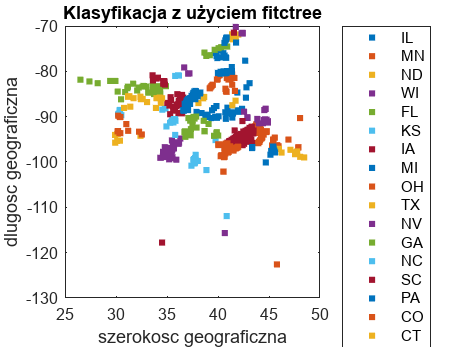

%utworzenie siatki punktów do wizualizacji
XtreeArray = table2array(Xtree);
YtreeArray = table2array(Ytree);
x1 = min(XtreeArray(:,1))-1:0.1:max(XtreeArray(:,1))+1;
x2 = min(XtreeArray(:,2))-1:0.1:max(XtreeArray(:,2))+1;
[x1Grid, x2Grid] = meshgrid(x1, x2);
XGrid = [x1Grid(:), x2Grid(:)];
%klasyfikacja punktów siatki
YGrid = predict(tree, XGrid);
%wykres przedstawiajacy klasyfikacje
figure;
Stree = gscatter(XtreeArray(:,1), XtreeArray(:,2), YtreeArray);
hold on;
title('Klasyfikacja z użyciem fitctree');
xlabel('szerokosc geograficzna');
ylabel('dlugosc geograficzna');
legend('Location', 'eastoutside');
hold off;